# Data-Driven Control Homework - SIDRA 2024 - Giorgio Ridolfi - Assignment 2 - Ex. 2b


clc
close all
clear all
rng(1);
%addpath("/home/gio/Scrivania/lezioni/lezione_assignment_datadriven_sidra_2024/datadriven_sidra2024/cvx/")
 
% cvx_setup


% Dimensions of system
nx = 4 ;
nu = 1;
ny = 1;
% Length of the input sequence
T = 10 ;

% Generating the input sequence u on [0,T-1] taking values in the interval
% [-1,1]^m in the form of an m x T matrix [u(0) u(1) .... u(T-1)]
magnitude=0.1;
aux=zeros(nu,T);
aux(:)=magnitude;
u(1:nu,1:T)=(2*magnitude).*rand(nu,T)-aux;
% Arranging the samples in the Hankel matrix U0 on [0,T-1]
for j=1:T-nu+1
    for i=1:nu
        U0((i-1)*nu+1:(i-1)*nu+nu,j)=u(1:nu, j+i-1);
    end
end
% If rank(U0)= m*L then the sequence u(0),...u(T-1) is PE of order L
if rank(U0) == nu*nu
    disp("input sequence is PE");
end

input sequence is PE



% Example 1
% Robot initial configuration and necessary data structures

x = zeros(4,T+1);
%   x_dot = x;
mx0 = 1;
x(:,1) = (2*mx0).*rand(nx,1)-mx0;

% System params, and matrices to write system in form x_dot = A*Z(x) + B*u
% + E*d
Kc = 0.4;
F2 = 0.15;
J2 = 0.2;
Nc = 2;
F1 = 0.1;
J1 = 0.15;
m = 0.4;
g = 9.8;
v = 0.1;
B = [ 0 0 0 1/J1]' ;
A = [ 0 1 0 0 0 ;
    -(Kc/J2) -(F2/J2) (Kc/(J2*Nc)) 0  -((m*g*v)/J2);
    0 0 0 1 0 ;
    -(Kc/(J1*Nc)) 0  (Kc/(J1*Nc)) -(F1/J1) 0 ];
C = [1 0 0 0 0 ];
size_Q = 1;
d_cst = [0.1 0.2 0.3 0.4 ]';
nd = 4;
E = eye(4);
A_bar = A(1:nx, 1:nx );
A_hat = A(1:nx , end+1-size_Q:end);
C_bar = C(1:ny, 1:nx );
C_hat = C(1:ny , end+1-size_Q:end);
A_call = [A_bar , zeros(nx,ny) , A_hat ;
          C_bar , zeros(ny , ny) , C_hat];
B_call = [ B ; zeros(ny , nu ) ];
E_call = [E ; zeros(ny , nd )];
I_call = [ zeros(nx, ny ) ; eye(ny ) ];


ref = pi/3; % track reference


% Define controller state space
xi = zeros(ny , T+1);
xi(1,1) = x(1,1) - ref;
% Stack into extended state space
l = [x ; xi ];
l_dot = zeros(nx+ny , T+1);


deltat = 0.1 ;

for t = 1 : T
    Z = [l(:,t) ; cos(l(1,t)) ];
    % Z = [l(:,t) ; cos(l(1,t)) ]; more nonlinearities
    l_dot(:,t) = A_call*Z + B_call*u(t) + E_call*d_cst - I_call*ref ;
    l(:,t+1) = l(:,t) + deltat*l_dot(:,t) ;
end


% Plot code taken from 
% https://github.com/zjhurug/codes-for-contraction-paper/blob/main/Ex1_one_link_robot_arm/one_link_robot_arm.m 
% and slightly modified
figure;
plot(l(1,:),'r','LineWidth',1.5); 

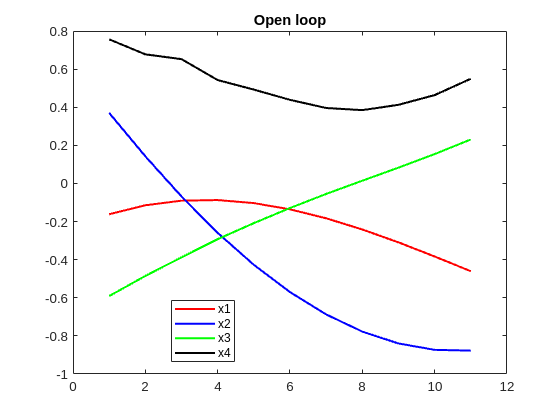

hold on;
plot(l(2,:),'b','LineWidth',1.5);
plot(l(3,:),'g','LineWidth',1.5);
plot(l(4,:),'k','LineWidth',1.5);
title('Open loop');
legend('x1','x2','x3','x4', 'Location', 'Best');
hold off;

Z1 = [l_dot(1:nx , 1:end-1) ; l(1 ,1:end-1) ];
Z0 = [l(:,1:end-1) ; cos(l(1,1:end-1))];

% Sanity check, should return a timeseries of disturbances
M = ones(1,T);
Z1 - ( A_call*Z0 + B_call*U0 );

RQ = [1 0 0 0 ; 0 0 0 0 ; 0 0 0 0 ; 0 0 0 0 ; 0 0 0 0 ];


r = nx; % column number of RQ
s = length(Z) - nu ; % number of nonlinearities, minus the augmented state


cvx_begin sdp
variable P1(nx+ny,nx+ny) symmetric
variable Y1(T,nx+ny)
variable G2(T,s-nx)
variable a
P1 >= 0*eye(nx+ny);
a >= 0;
Z0*Y1 == [P1;zeros(s-nx,nx+ny)];
[Z1*Y1+transpose(Z1*Y1)+a*eye(nx+ny) Z1*G2 P1*RQ;
    transpose(Z1*G2) -eye(s-nx) zeros(s-nx,r);
    transpose(P1*RQ) zeros(r,s-nx) -eye(r)] <= 0;
Z0*G2 == [zeros(nx+ny,s-nx);eye(s-nx)];
M*[Y1 G2] == zeros(1,s+ny);
cvx_end

 
Calling SDPT3 4.0: 109 variables, 72 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 72
 dim. of sdp    var  = 15,   num. of sdp  blk  =  2
 dim. of linear var  =  1
 dim. of free   var  = 38 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.4e+02|1.8e+02|4.4e+05| 5.000000e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.928|0.895|9.8e+00|1.9e+01|9.9e+03| 4.011697e+01  0.000000e+00| 0:0:00| chol  1  1 
 2|0.853|0.910|1.4e+00|1.8e+00|2.6e+02| 2.486722e+01  0.000000e+00| 0:0:0

G1 = Y1/P1;
G  = [G1 G2];
K  = U0*G;


%Simulate closed loop system

T =  40*T;
x = zeros(4,T+1);
x(:,1) = [0 0 0 0]';
% Define controller state space
xi = zeros(ny , T+1);
xi(1,1) = x(1,1) - r;
% Stack into extended state space
l = [x ; xi ];
l_dot = zeros(nx+ny , T+1);
for t = 1 : T
    Z = [l(:,t) ; cos(l(1,t)) ];
    % Z = [l(:,t) ; cos(l(1,t)) ]; more nonlinearities
    l_dot(:,t) = (A_call + B_call*K)*Z  + E_call*d_cst - I_call*ref ;
    l(:,t+1) = l(:,t) + deltat*l_dot(:,t) ;
end


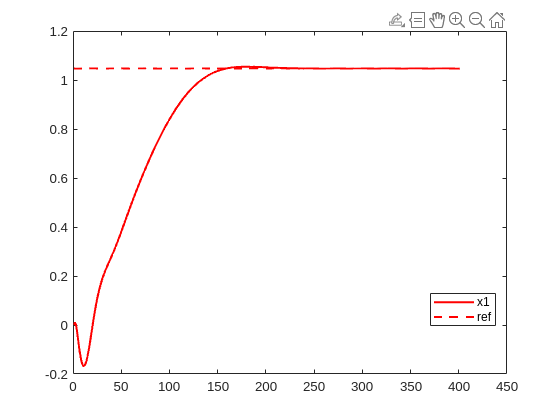


% Plot code taken from 
% https://github.com/zjhurug/codes-for-contraction-paper/blob/main/Ex1_one_link_robot_arm/one_link_robot_arm.m 
% and slightly modified
figure;
plot(l(1,:),'r','LineWidth',1.5); 
hold on;
plot(ref.*ones(1,T),'--r','LineWidth',1.5);
%title('Closed loop');
legend('x1','ref', 'Location', 'Best');
hold off;